Here are 5-year averages of the worldwide temperature anomaly as compared to the 1951-1980 average (source: NASA).

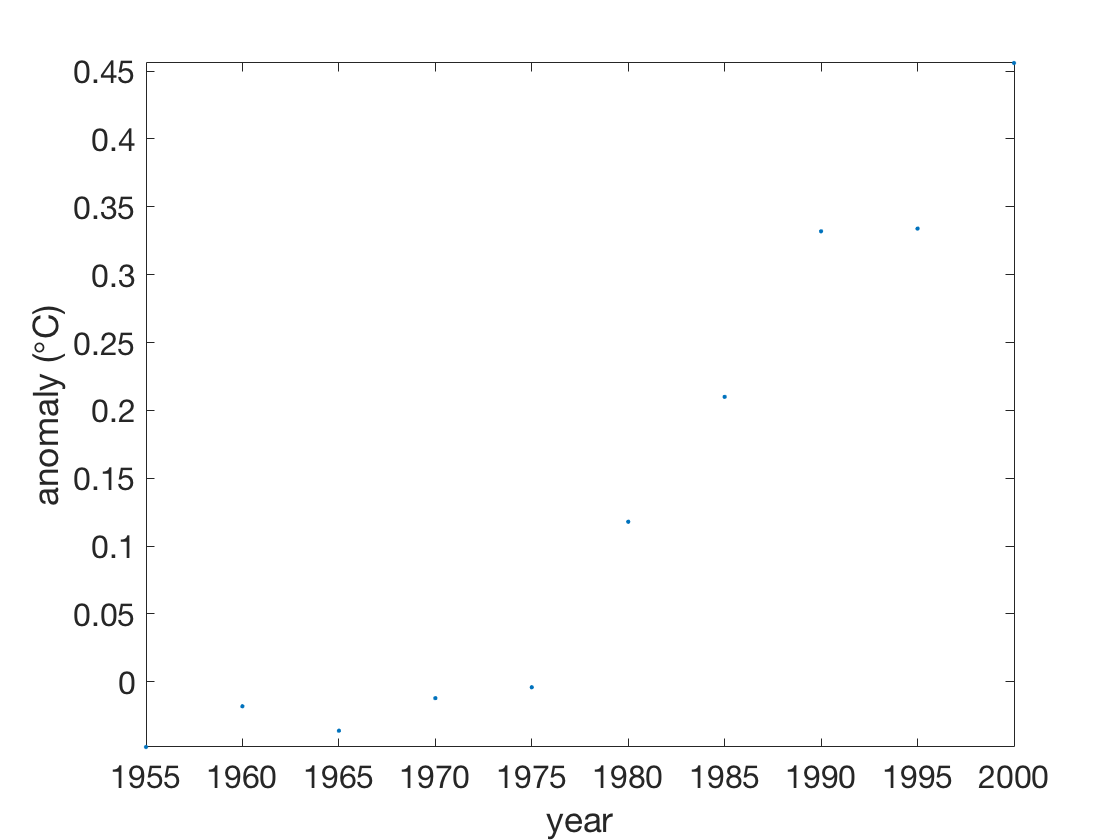

t = (1955:5:2000)';
y = [ -0.0480; -0.0180; -0.0360; -0.0120; -0.0040;
    0.1180; 0.2100; 0.3320; 0.3340; 0.4560 ];
plot(t,y,'.')
xlabel('year'), ylabel('anomaly ({\circ}C)'), axis tight   % ignore this line

A polynomial interpolant can be used to fit the data. Here we build one using a Vandermonde matrix. First, though, we express time as decades since 1950, as it improves the condition number of the matrix. 

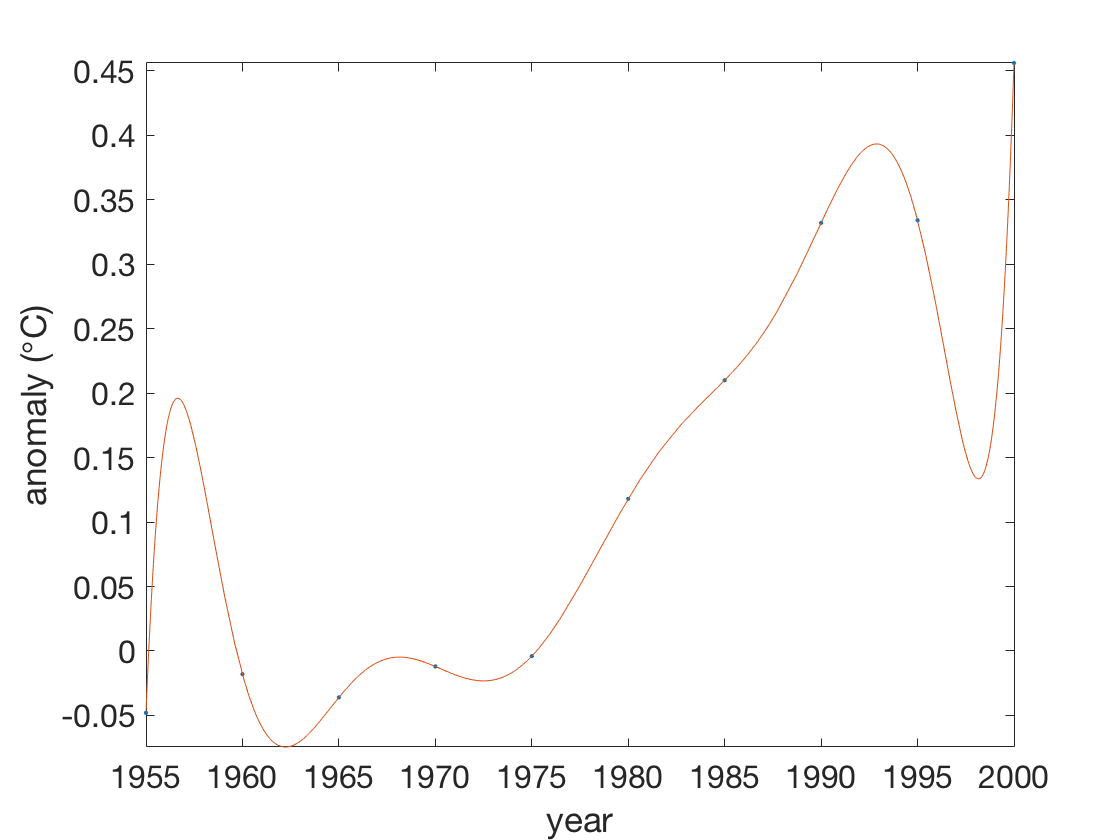

t = (t-1950)/10;  
V = t.^0;      % vector of ones
n = length(t);
for j = 1:n-1
    V(:,j+1) = t.*V(:,j);
end
c = V\y;
p = @(x) polyval(flipud(c),(x-1950)/10);
hold on, fplot(p,[1955 2000])

As you can see, the interpolant does represent the data, in a sense. However it's a crazy-looking curve for the application. Trying too hard to reproduce all the data exactly is known as *overfitting*.